## **HCP Node Measure Assignments **

This script builds a positive and negative Node-Measure Assignment (NMA) for the complete sample, plots the NMAs, the grouped NMAs and the mean coupling for the NMAs.

Before Running this Script: 

- Run HCP_compute_coupling_measures 

- Run  setup_data & example from visualization folder 

**Before Start: Create All_Nodes_complete_baseline_best_measures_HCP_weighted_only (a cell that contains for each subject a vector of 8 predictors for each node) **

for i = 1:1030
    x = final_r_all_HCP_1030_new{i,1};
    for j = 1:358
    Node_all_baseline_best_measures_HCP_weighted_only{i,j} = x(j,:);
    end
end


**Before Start: Create cell that contains information from all subjects and all coupling measures for all nodes separetely (1030*8)**

% extract for each collumn 8 rows from each row and put them together in a matrix (--> I need 1030*8 Matrix for each Node)

n = size(Node_all_baseline_best_measures_HCP_weighted_only,2);
All_Nodes_complete_baseline_best_measures_HCP_weighted_only = cell(1,n);
for j = 1:n
    All_Nodes_complete_baseline_best_measures_HCP_weighted_only{j} = vertcat(Node_all_baseline_best_measures_HCP_weighted_only{:,j});
end 

**1) Assign the behavioral variables **

Intelligence_HCP = HCP_behavioral_1030.G_Factor;
ALter_HCP = HCP_behavioral_1030.Age;
Gender_HCP = HCP_behavioral_1030.("Gender num");
Motion_HCP = HCP_behavioral_1030.Mean_mean_FD;
Handedness_HCP = HCP_behavioral_1030.Handedness;

**2) Build a positive and negative Node-Measure-Assignment**

2.1) for each node, correlate coupling-measure specific coupling values with cognitive ability scores

% Preallocation

Correlation_com_measures_fold_rho = zeros(358,8);
Correlation_com_measure_fold_pval = zeros(358,8);

for i = 1:358 % do for each node separately
    All_Communication_measures_per_node = All_Nodes_complete_baseline_best_measures_HCP_weighted_only{1,i};
    
     for p = 1:8 % correlate each measure with cognitive ability scores
        Communication_Measure_separate = All_Communication_measures_per_node(:,p);
        
             % Correlation

                x = [Communication_Measure_separate, Intelligence_HCP];
                z = [ALter_HCP, Gender_HCP, Motion_HCP, Handedness_HCP]; % control variables
   
                [rho,pval] = partialcorr(x,z);
                
                rho = rho(1,2);
                pval = pval(1,2);
            
               Correlation_com_measures_fold_rho(i,p) = rho;
               Correlation_com_measure_fold_pval(i,p) = pval;

        
    end
end

2.2) Find out which coupling measure has the highest positive association with cognitive ability

for i = 1:358
    Correlation_rho_per_node = Correlation_com_measures_fold_rho(i,:);
    Max_Rho = max(Correlation_rho_per_node);
    Idx_max_rho = find(Correlation_rho_per_node == Max_Rho);
    Info_best_performing_communication_measure_pos_HCP_wei{i,1} = Max_Rho;
    Info_best_performing_communication_measure_pos_HCP_wei{i,2} = Idx_max_rho;
end

2.3) Find out which coupling measure has the highest negative association with cognitive ability 

for i = 1:358
    Correlation_rho_per_node = Correlation_com_measures_fold_rho(i,:);
    Min_Rho = min(Correlation_rho_per_node);
    Idx_min_rho = find(Correlation_rho_per_node == Min_Rho);
    Info_best_performing_communication_measure_neg_HCP_wei{i,1} = Min_Rho;
    Info_best_performing_communication_measure_neg_HCP_wei{i,2} = Idx_min_rho;
end


2.4) Save the Node Measure Assignments 

best_performing_measure_per_node_pos_HCP_wei = cell2mat(Info_best_performing_communication_measure_pos_HCP_wei(:,2)')

best_performing_measure_per_node_pos_HCP_wei =      5     5     5     5     5     5     5     5     5     3     2     2     5     5     5     1     8     3     5     5     1     1     8     6     6     5     6     5     7     3     4     5     1     8     1     5     6     5     5     5     6     6     5     5     5     5     8     5     6     8


best_performing_measure_per_node_neg_HCP_wei = cell2mat(Info_best_performing_communication_measure_neg_HCP_wei(:,2)')

best_performing_measure_per_node_neg_HCP_wei =      7     7     6     1     2     8     8     4     4     7     7     5     6     8     2     6     4     6     8     6     6     6     6     8     2     6     4     7     6     6     6     4     5     6     6     4     1     1     4     4     1     1     7     2     3     3     7     4     4     7


**3) Extract the best case scenario values for the positive NMA**

Best_case_scenario_r_values_pos_HCP = zeros(358,1030);

for i = 1:358
    index = best_performing_measure_per_node_pos_HCP_wei(i);
    Best_scenario_node_values = All_Nodes_complete_baseline_best_measures_HCP_weighted_only{1,i}(:,index); 
    
    Best_case_scenario_r_values_pos_HCP(i,:) = Best_scenario_node_values';
end

Best_case_scenario_r_values_pos_HCP = Best_case_scenario_r_values_pos_HCP';

**4) Extract the best case scenario values for the negative NMA**

Best_case_scenario_r_values_neg_HCP = zeros(358,1030);

for i = 1:358
    index = best_performing_measure_per_node_neg_HCP_wei(i);
    Best_scenario_node_values_neg = All_Nodes_complete_baseline_best_measures_HCP_weighted_only{1,i}(:,index); 
    
    Best_case_scenario_r_values_neg_HCP(i,:) = Best_scenario_node_values_neg';
end

Best_case_scenario_r_values_neg_HCP = Best_case_scenario_r_values_neg_HCP';


**5) Insert 0's at node 120 and 300 (because there is no data and I deleted information from those 2 nodes at the start)**

5.1) positive NMA 

a = best_performing_measure_per_node_pos_HCP_wei;
b = 0;
idx_120 = 120; 
idx_300 = 300;

a = [a(1:length(a)< idx_120),b,a(1:length(a) >= idx_120)];
a = [a(1:length(a)< idx_300),b,a(1:length(a) >= idx_300)];

best_performing_measure_per_node_pos_HCP_360_wei = a;

5.2) negative NMA 

a = best_performing_measure_per_node_neg_HCP_wei; 
b = 0;
idx_120 = 120; 
idx_300 = 300;

a = [a(1:length(a)< idx_120),b,a(1:length(a) >= idx_120)];
a = [a(1:length(a)< idx_300),b,a(1:length(a) >= idx_300)];

best_performing_measure_per_node_neg_HCP_360_wei = a;

**6) Plot the NMA's **

6.1) Positive NMA

best_performing_measure_per_node_pos_HCP_360_wei(120) = NaN;
best_performing_measure_per_node_pos_HCP_360_wei(300) = NaN;

**1) Diffusion - based Measures **

2 (Communicability) = 1

7 (Mean first passage time) = 2

8 (Flow Graphs) = 3 

**2) Path Accessibliity Measures **

4 (Search Information) = 4 

5 (Path Transitivity) = 5 

**3) Routing Measures**

1 (Path Length) = 6

**4) Similarity Measures**

3 (Cosine Distance) = 7 

6 (Matching Index) = 8 

vector_pos_bcs = best_performing_measure_per_node_pos_HCP_360_wei;

% Diffusion
vector_pos_bcs(vector_pos_bcs == 2) = 100;  % communicability
vector_pos_bcs(vector_pos_bcs == 7) = 200;  % mean first passage time
vector_pos_bcs(vector_pos_bcs == 8) = 300;  % flow graphs 


% Path Accessibility
vector_pos_bcs(vector_pos_bcs == 4) = 500; % search information
vector_pos_bcs(vector_pos_bcs == 5) = 600; % path transitivity 

% Routing 
vector_pos_bcs(vector_pos_bcs == 1) = 800; % path length


% Similarity
vector_pos_bcs(vector_pos_bcs == 3) = 1000; % cosine distance
vector_pos_bcs(vector_pos_bcs == 6) = 1100; % matching index 


annotName = 'hcp-mmp-b';
dataVec = vector_pos_bcs

dataVec =          600         600         600         600         600         600         600         600         600        1000         100         100         600         600         600         800         300        1000         600         600         800         800         300        1100        1100         600        1100         600         200        1000         500         600         800         300         800         600        1100         600         600         600        1100        1100         600         600         600         600         300         600        1100         300


ans = struct with fields:
      border: 1
        cMap: [11×3 double]
      newFig: 1
    valRange: [100 1100]
    viewcMap: 1
     viewStr: 'all'


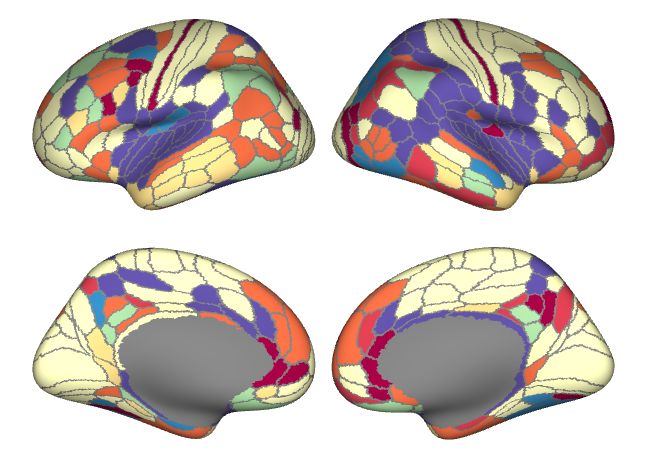

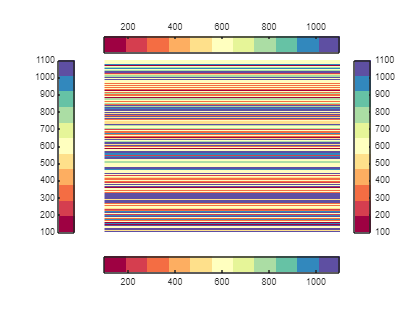

ans = 4×1 cell array
    {1×1 Patch}
    {1×1 Patch}
    {1×1 Patch}
    {1×1 Patch}


parc_plot(surfStruct,annotMap,annotName,dataVec, 'cMap',brewermap(11,'Spectral'),...
    'viewcMap',1, 'ValRange', ([100 1100]))

6.2) Negative NMA

best_performing_measure_per_node_neg_HCP_360_wei(120) = NaN;
best_performing_measure_per_node_neg_HCP_360_wei(300) = NaN; 


**1) Diffussion - based measures **

2 (Communicability) = 1

7 (Mean first passage time) = 2

8 (Flow Graphs) = 3 

**2) Path Accessibility Measures **

4 (Search Information) = 4 

5 (Path Transitivity) = 5 

**3) Routing Measures**

1 (Path Length) = 6

**4) Similarity Measures**

3 (Cosine Distance) = 7 

6 (Matching Index) = 8 

vector_neg_bcs = best_performing_measure_per_node_neg_HCP_360_wei;

% Diffusion
vector_neg_bcs(vector_neg_bcs == 2) = 100;  % communicability
vector_neg_bcs(vector_neg_bcs == 7) = 200;  % mean first passage time
vector_neg_bcs(vector_neg_bcs == 8) = 300;  % flow graphs 


% Path Accessibility
vector_neg_bcs(vector_neg_bcs == 4) = 500; % search information
vector_neg_bcs(vector_neg_bcs == 5) = 600; % path transitivity 

% Routing 
vector_neg_bcs(vector_neg_bcs == 1) = 800; % path length


% Similarity
vector_neg_bcs(vector_neg_bcs == 3) = 1000; % cosine distance
vector_neg_bcs(vector_neg_bcs == 6) = 1100; % matching index 


annotName = 'hcp-mmp-b';
dataVec = vector_neg_bcs

dataVec =          200         200        1100         800         100         300         300         500         500         200         200         600        1100         300         100        1100         500        1100         300        1100        1100        1100        1100         300         100        1100         500         200        1100        1100        1100         500         600        1100        1100         500         800         800         500         500         800         800         200         100        1000        1000         200         500         500         200


ans = struct with fields:
      border: 1
        cMap: [11×3 double]
      newFig: 1
    valRange: [100 1100]
    viewcMap: 1
     viewStr: 'all'


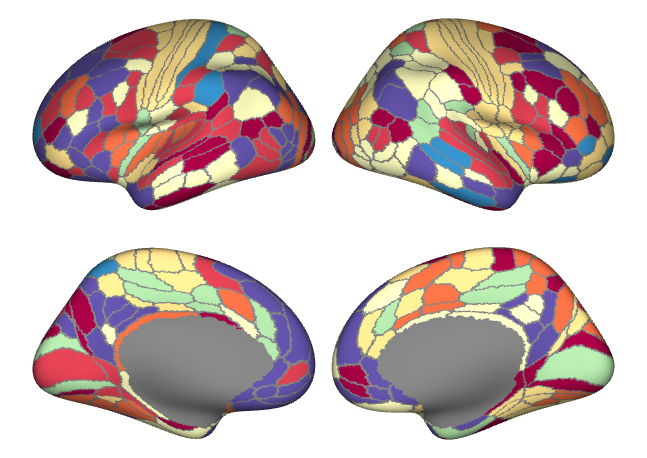

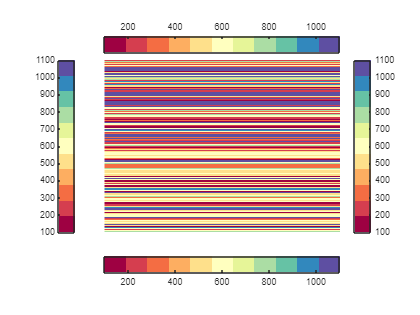

ans = 4×1 cell array
    {1×1 Patch}
    {1×1 Patch}
    {1×1 Patch}
    {1×1 Patch}


parc_plot(surfStruct,annotMap,annotName,dataVec, 'cMap',brewermap(11,'Spectral'),...
    'viewcMap',1, 'ValRange', ([100 1100]))

**7) Plot the Coupling strength for the NMAs**

7.1) Average the correlation for mean NMA's

Mean_correlation_best_case_scenario_pos = mean(Best_case_scenario_r_values_pos_HCP);
Mean_correlation_best_case_scenario_neg = mean(Best_case_scenario_r_values_neg_HCP);

7.2) Insert 0's at node 120 and 300 (because there is no data and I deleted information from those 2 nodes at the start)

7.2.1) Positive NMA 

a = Mean_correlation_best_case_scenario_pos;
b = 0;
idx_120 = 120;
idx_300 = 300;

a = [a(1:length(a)< idx_120),b,a(1:length(a) >= idx_120)];
a = [a(1:length(a)< idx_300),b,a(1:length(a) >= idx_300)];

Mean_correlation_best_case_scenario_pos_360 = a;

7.2.2) Negative NMA 

a = Mean_correlation_best_case_scenario_neg; 
b = 0;
idx_120 = 120;
idx_300 = 300;

a = [a(1:length(a)< idx_120),b,a(1:length(a) >= idx_120)];
a = [a(1:length(a)< idx_300),b,a(1:length(a) >= idx_300)];

Mean_correlation_best_case_scenario_neg_360 = a;

**8) Plot the mean coupling strength**

8.1.) Positive NMA

ans = struct with fields:
      border: 1
        cMap: [15×3 double]
      newFig: 1
    valRange: [-0.5500 0.5500]
    viewcMap: 1
     viewStr: 'all'


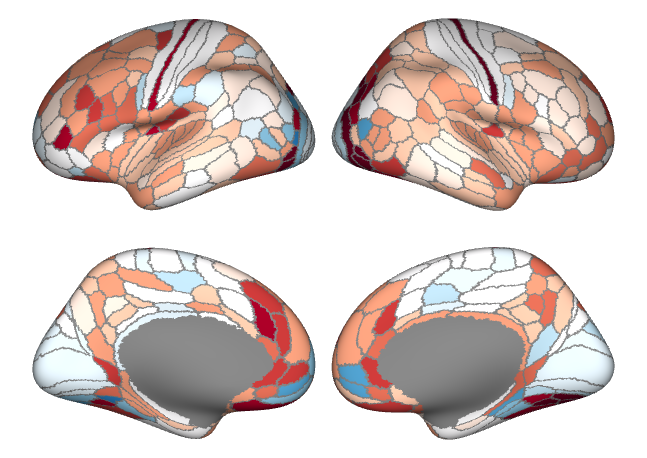

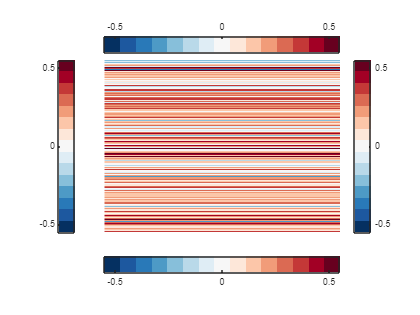

ans = 4×1 cell array
    {1×1 Patch}
    {1×1 Patch}
    {1×1 Patch}
    {1×1 Patch}


annotName = 'hcp-mmp-b';
dataVec = Mean_correlation_best_case_scenario_pos_360;
parc_plot(surfStruct,annotMap,annotName,dataVec,'cMap',brewermap(15,'*RdBu'),...
    'viewcMap',1, 'valRange', ([-0.55 0.55]))

8.2.) Negative NMA 

ans = struct with fields:
      border: 1
        cMap: [15×3 double]
      newFig: 1
    valRange: [-0.5500 0.5500]
    viewcMap: 1
     viewStr: 'all'


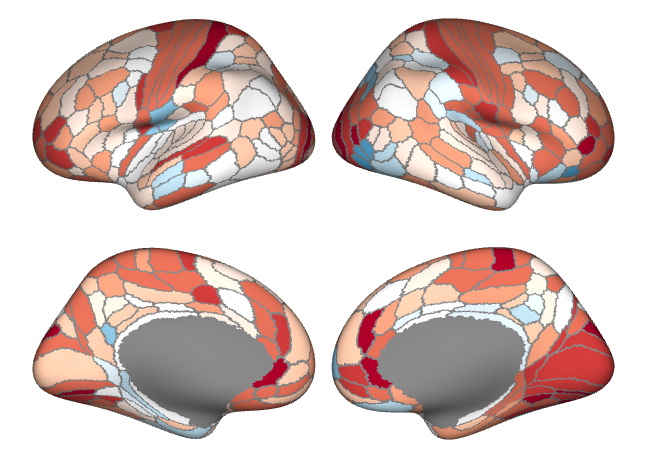

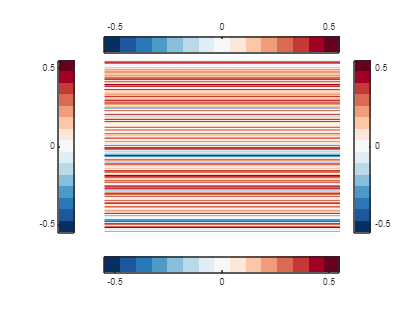

ans = 4×1 cell array
    {1×1 Patch}
    {1×1 Patch}
    {1×1 Patch}
    {1×1 Patch}


annotName = 'hcp-mmp-b';
dataVec = Mean_correlation_best_case_scenario_neg_360;
parc_plot(surfStruct,annotMap,annotName,dataVec, 'cMap',brewermap(15,'*RdBu'),...
    'viewcMap',1, 'valRange', ([-0.55 0.55]))

**9) Assign the Coupling Measures to Groups (Based on Literature)**

9.1) Positive NMA

1) Diffusion-based communication measures (communicability; mean first passage time & flow graphs) 

2) Communication measures capturing path accessibility (path transitivity & search information)

3) Routing-based communication measures (path length) 

4) Similarity measures (cosine distance & matching index) 

% Diffusion-based (100) = 2,7,8
% Path Accessibility (300) = 5,4
% Routing (500) = 1
% Similarity (600) =  3,6

vector_pos_bcs = best_performing_measure_per_node_pos_HCP_360_wei;

% Diffusion = 100 
vector_pos_bcs(vector_pos_bcs == 2) = 100;
vector_pos_bcs(vector_pos_bcs == 7) = 100;
vector_pos_bcs(vector_pos_bcs == 8) = 100;


% Path Accessibility = 300 
vector_pos_bcs(vector_pos_bcs == 5) = 300;
vector_pos_bcs(vector_pos_bcs == 4) = 300;

% Routing = 500 
vector_pos_bcs(vector_pos_bcs == 1) = 500;


% Similarity = 600
vector_pos_bcs(vector_pos_bcs == 3) = 600;
vector_pos_bcs(vector_pos_bcs == 6) = 600;


9.2) Plot the groups (positive NMA)

annotName = 'hcp-mmp-b';
dataVec = vector_pos_bcs

dataVec =    300   300   300   300   300   300   300   300   300   600   100   100   300   300   300   500   100   600   300   300   500   500   100   600   600   300   600   300   100   600   300   300   500   100   500   300   600   300   300   300   600   600   300   300   300   300   100   300   600   100


ans = struct with fields:
      border: 1
        cMap: [6×3 double]
      newFig: 1
    valRange: [100 600]
    viewcMap: 1
     viewStr: 'all'


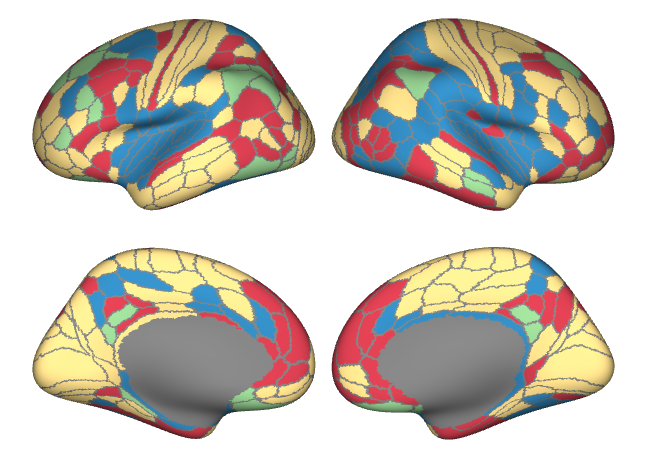

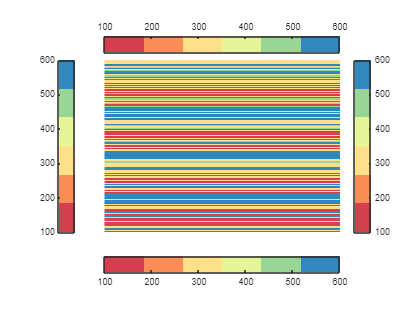

ans = 4×1 cell array
    {1×1 Patch}
    {1×1 Patch}
    {1×1 Patch}
    {1×1 Patch}


parc_plot(surfStruct,annotMap,annotName,dataVec, 'cMap',brewermap(6,'Spectral'),...
    'viewcMap',1, 'ValRange', ([100,600]))

9.3) Negative NMA 

1) Diffusion-based communication measures (communicability; mean first passage time & flow graphs) 

2) Communication measures capturing path accessibility (path transitivity & search information)

3) Routing-based communication measures (path length) 

4) Similarity measures (cosine distance & matching index) 

% Diffusion-based (100) = 2,7,8
% Path Accessibility (200) = 5,4
% Routing (300) = 1
% Similarity (400) =  3,6

vector_neg_bcs = best_performing_measure_per_node_neg_HCP_360_wei;

% Diffusion = 100 
vector_neg_bcs(vector_neg_bcs == 2) = 100;
vector_neg_bcs(vector_neg_bcs == 7) = 100;
vector_neg_bcs(vector_neg_bcs == 8) = 100;


% Path Accessibility = 300 
vector_neg_bcs(vector_neg_bcs == 5) = 300;
vector_neg_bcs(vector_neg_bcs == 4) = 300;

% Routing = 500 
vector_neg_bcs(vector_neg_bcs == 1) = 500;


% Similarity = 600
vector_neg_bcs(vector_neg_bcs == 3) = 600;
vector_neg_bcs(vector_neg_bcs == 6) = 600;


9.4) Plot the groups (neg NMA)

ans = struct with fields:
      border: 1
        cMap: [6×3 double]
      newFig: 1
    valRange: [100 600]
    viewcMap: 1
     viewStr: 'all'


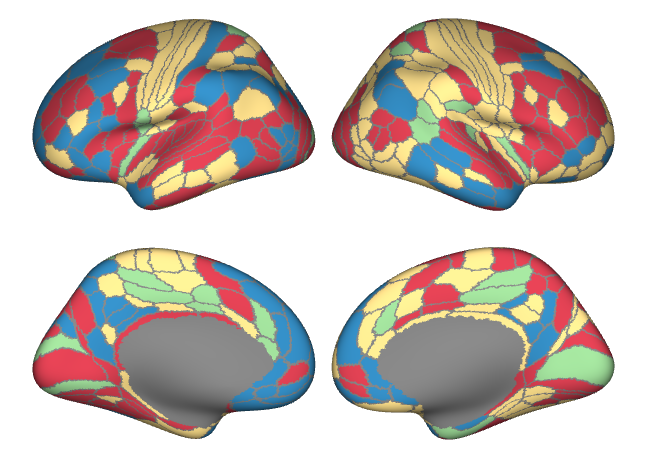

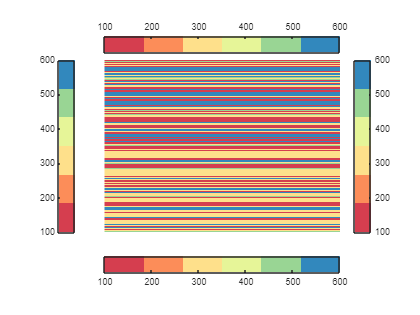

ans = 4×1 cell array
    {1×1 Patch}
    {1×1 Patch}
    {1×1 Patch}
    {1×1 Patch}


annotName = 'hcp-mmp-b';
dataVec = vector_neg_bcs;
parc_plot(surfStruct,annotMap,annotName,dataVec, 'cMap',brewermap(6,'Spectral'),...
    'viewcMap',1, 'ValRange', ([100,600]))